# Practice 3  Mathematical model of piezoelectric actuator

                                                                                                Name: Zhu Chenhao  

                                                                                                HDU ID: 22320630  

                                                                                                ITMO ID: 375462

Variant : 2

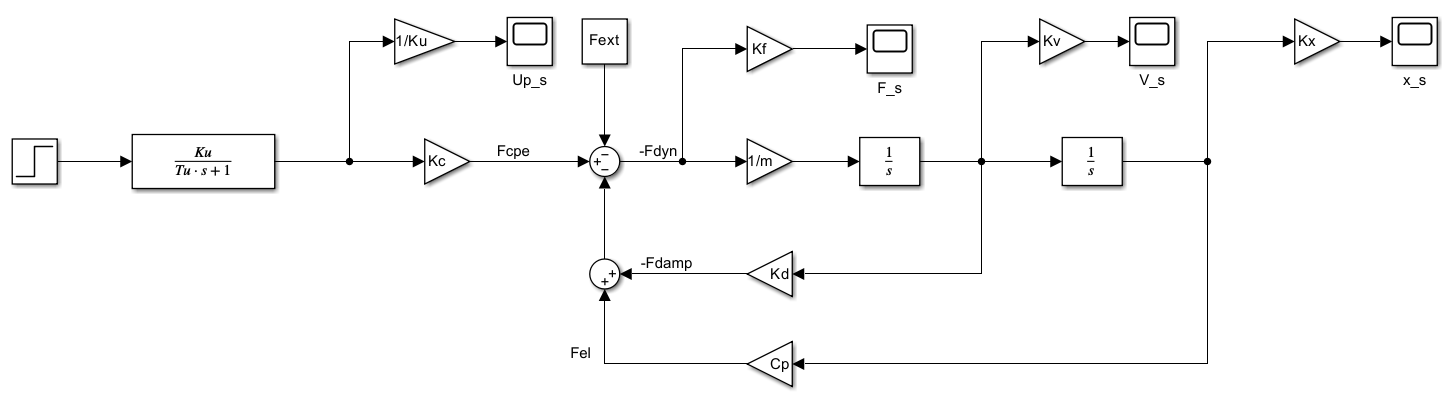

## 1. Compute the parameters of piezoelectric motor.

model_name = "prac3s2022a.slx";
k = 2;
variant = get_pm_variant(k);
disp(variant);

          Cp       m     Kc     Kd      Tu      Fext
         _____    ___    ___    ___    _____    ____

    2    5e+07    0.3    8.2    900    6e-05     80 



Upm = 300;
Um = 10;
Ku = Upm/Um;
Kf = 0.1;
Kv = 0.1;
Kx = 0.1;

## 2. Obtain transient processes: Fext = 0 and U = 10.

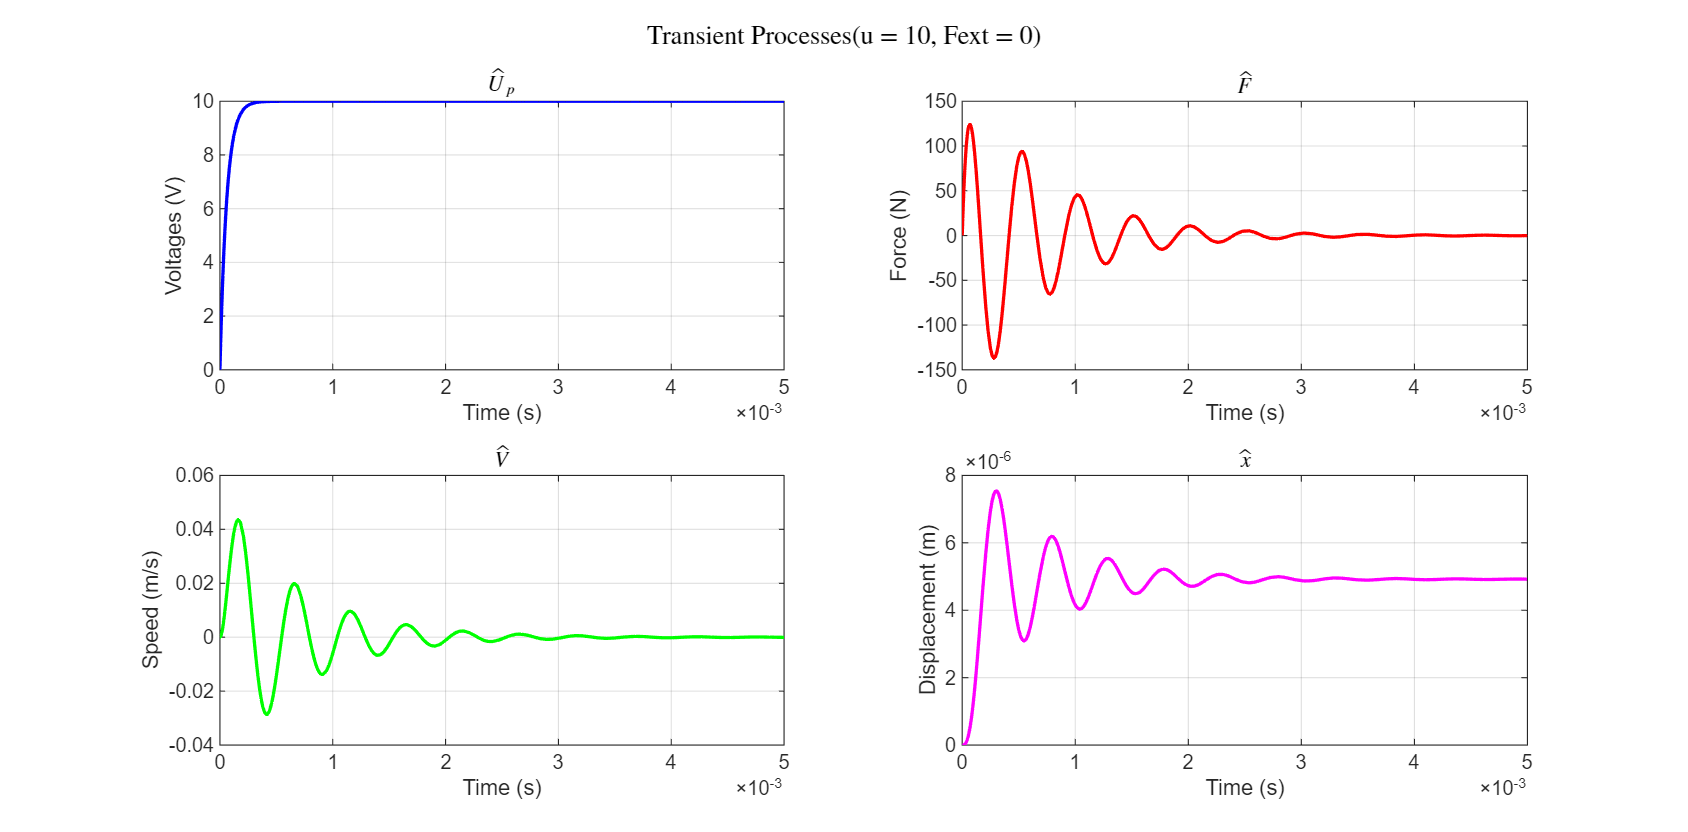

init_variant(variant);
Fext = 0;
u = 10;

Tmdl = 0.009;

## 3. m within ±50%

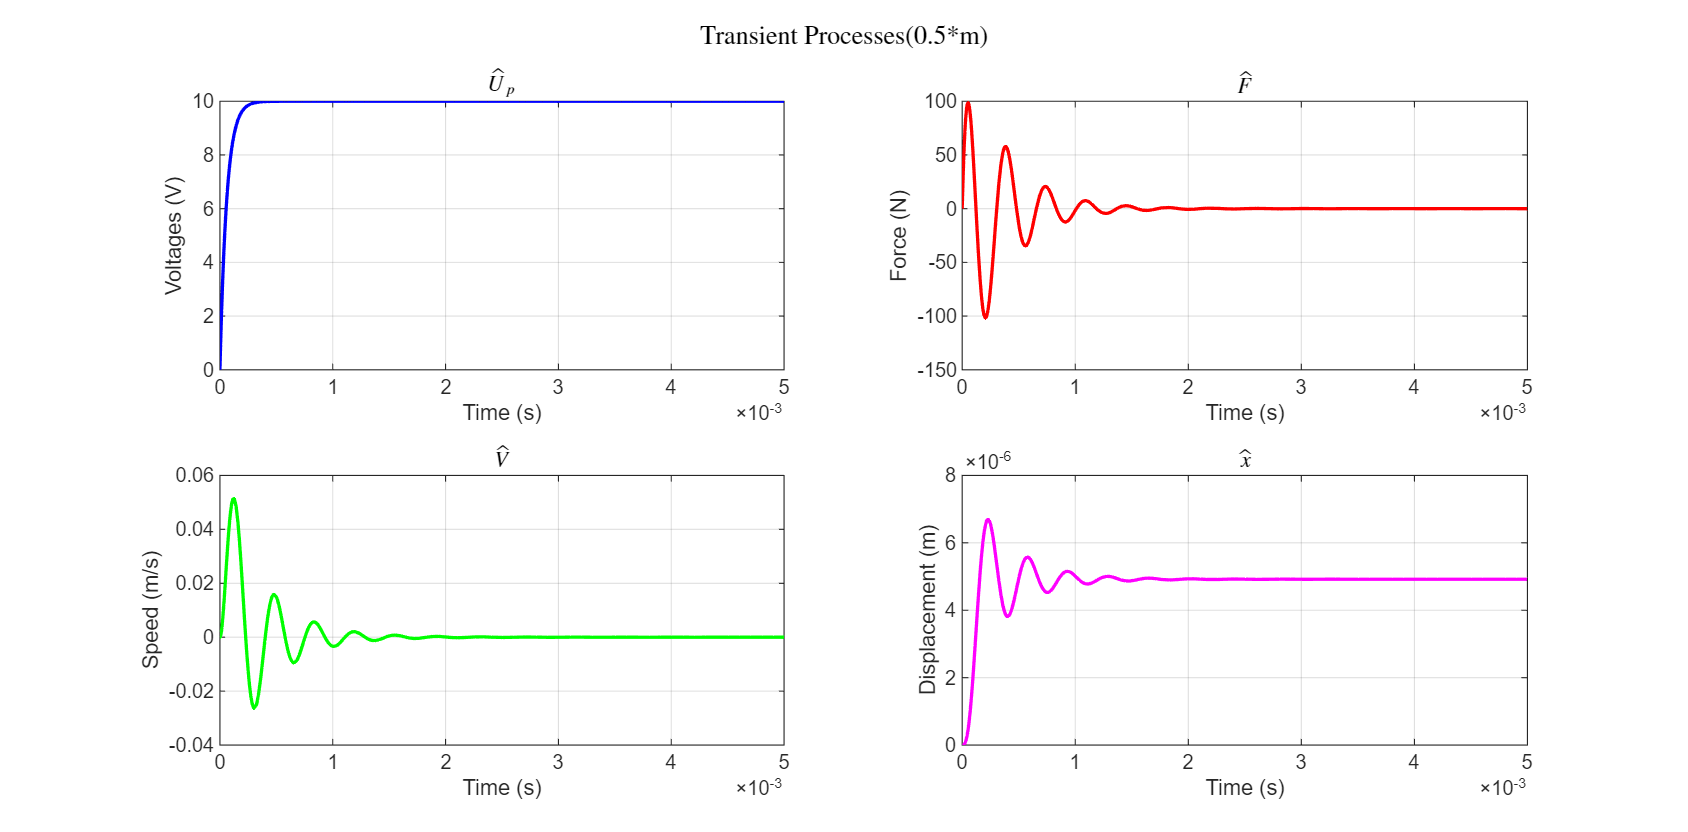

m = 0.5*variant.m;

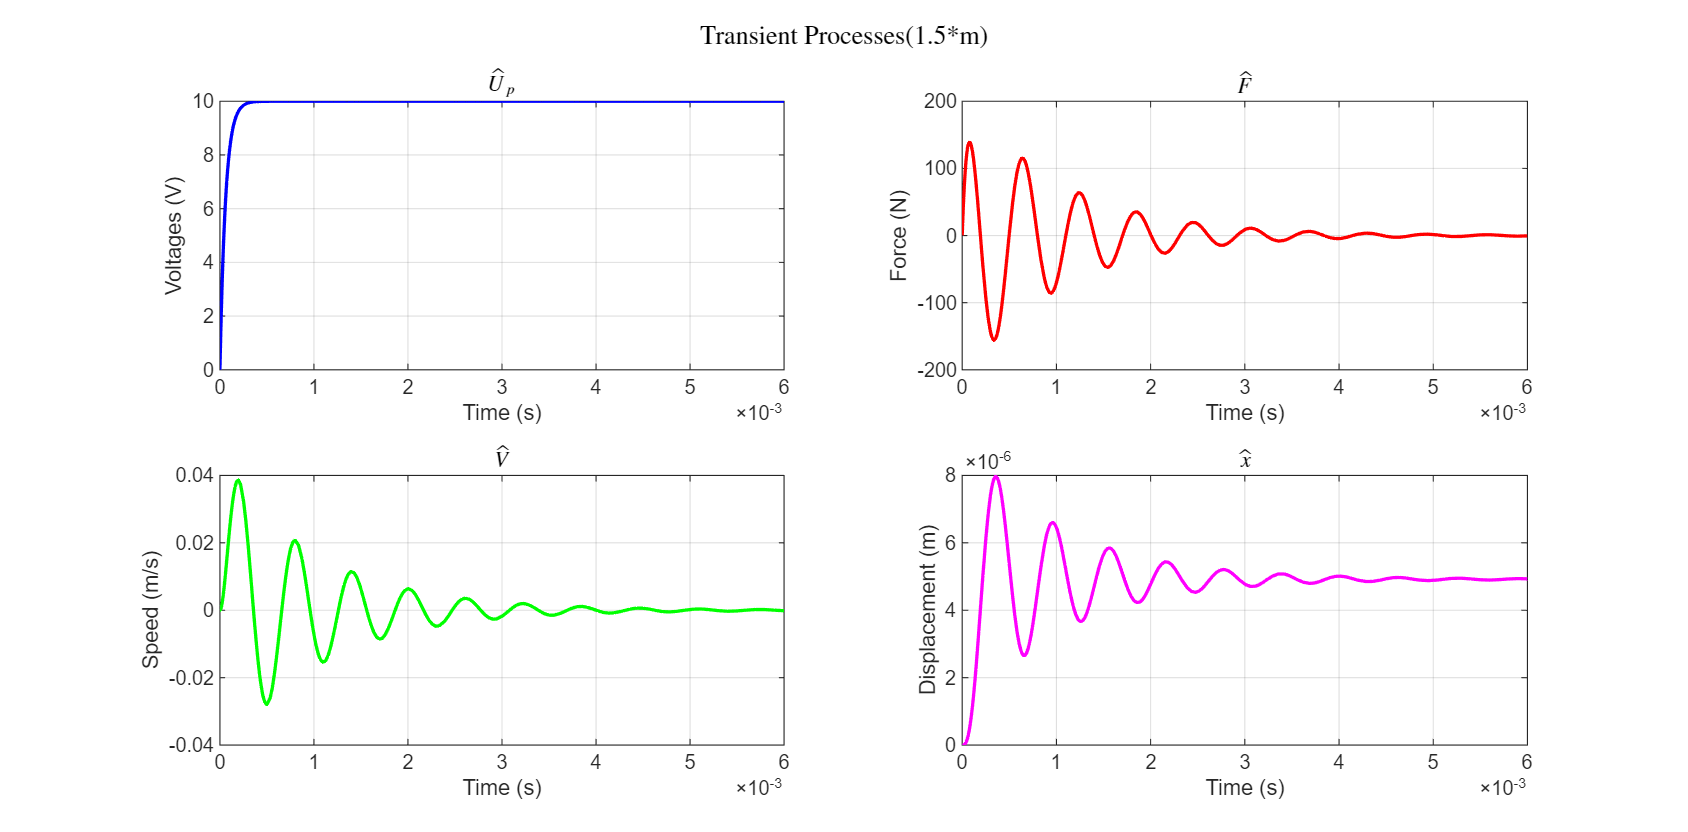

m = 1.5*variant.m;

## 4. Different values of Tu.

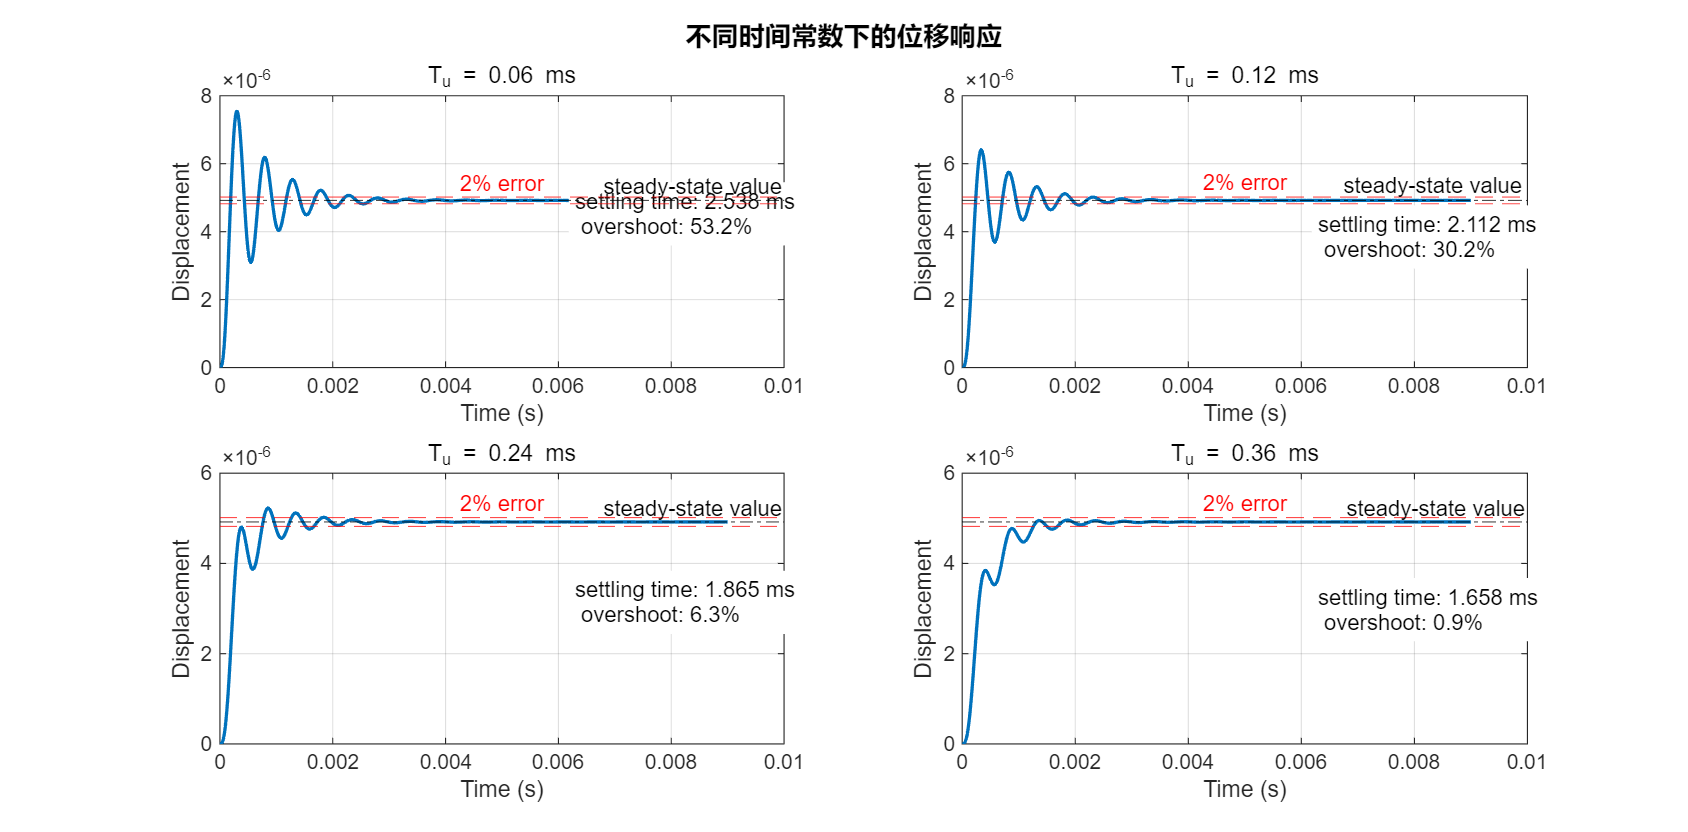

特征根分析结果:

Tu = 0.06 ms时的特征根:
   1.0e+04 *

  -1.6667 + 0.0000i
  -0.1500 + 1.2823i
  -0.1500 - 1.2823i


Tu = 0.12 ms时的特征根:
   1.0e+04 *

  -0.1500 + 1.2823i
  -0.1500 - 1.2823i
  -0.8333 + 0.0000i


Tu = 0.24 ms时的特征根:
   1.0e+04 *

  -0.1500 + 1.2823i
  -0.1500 - 1.2823i
  -0.4167 + 0.0000i


Tu = 0.36 ms时的特征根:
   1.0e+04 *

  -0.1500 + 1.2823i
  -0.1500 - 1.2823i
  -0.2778 + 0.0000i

性能指标汇总:
    times    Tu_ms    settling time(ms)    overshoot(%)    steady-state value(xss)
    _____    _____    _________________    ____________    _______________________

      1      0.06          2.5379             53.229              4.92e-06        
      2      0.12          2.1118             30.208              4.92e-06        
      4      0.24           1.865             6.2974              4.92e-06        
      6      0.36          1.6581            0.87616              4.92e-06        



% 调用分析函数
init_variant(variant);
Fext = 0;
u = 10;
% Tu = 2*variant.Tu;

% Tu = 4*variant.Tu;

% Tu = 6*variant.Tu;

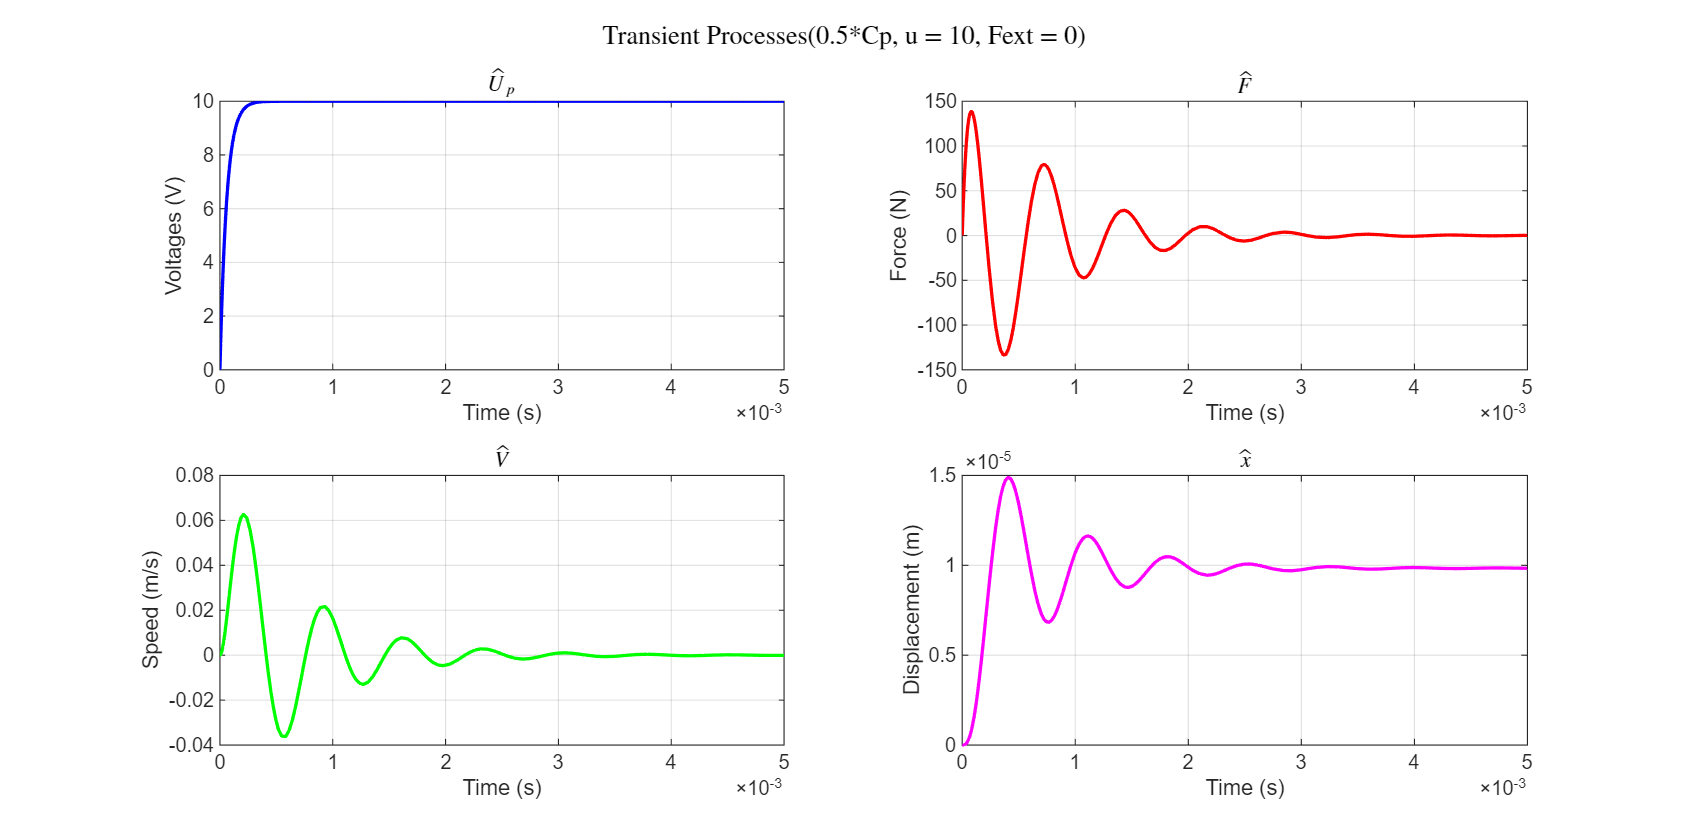

init_variant(variant);
Fext = 0;
u = 10;
Cp = 0.5*variant.Cp;


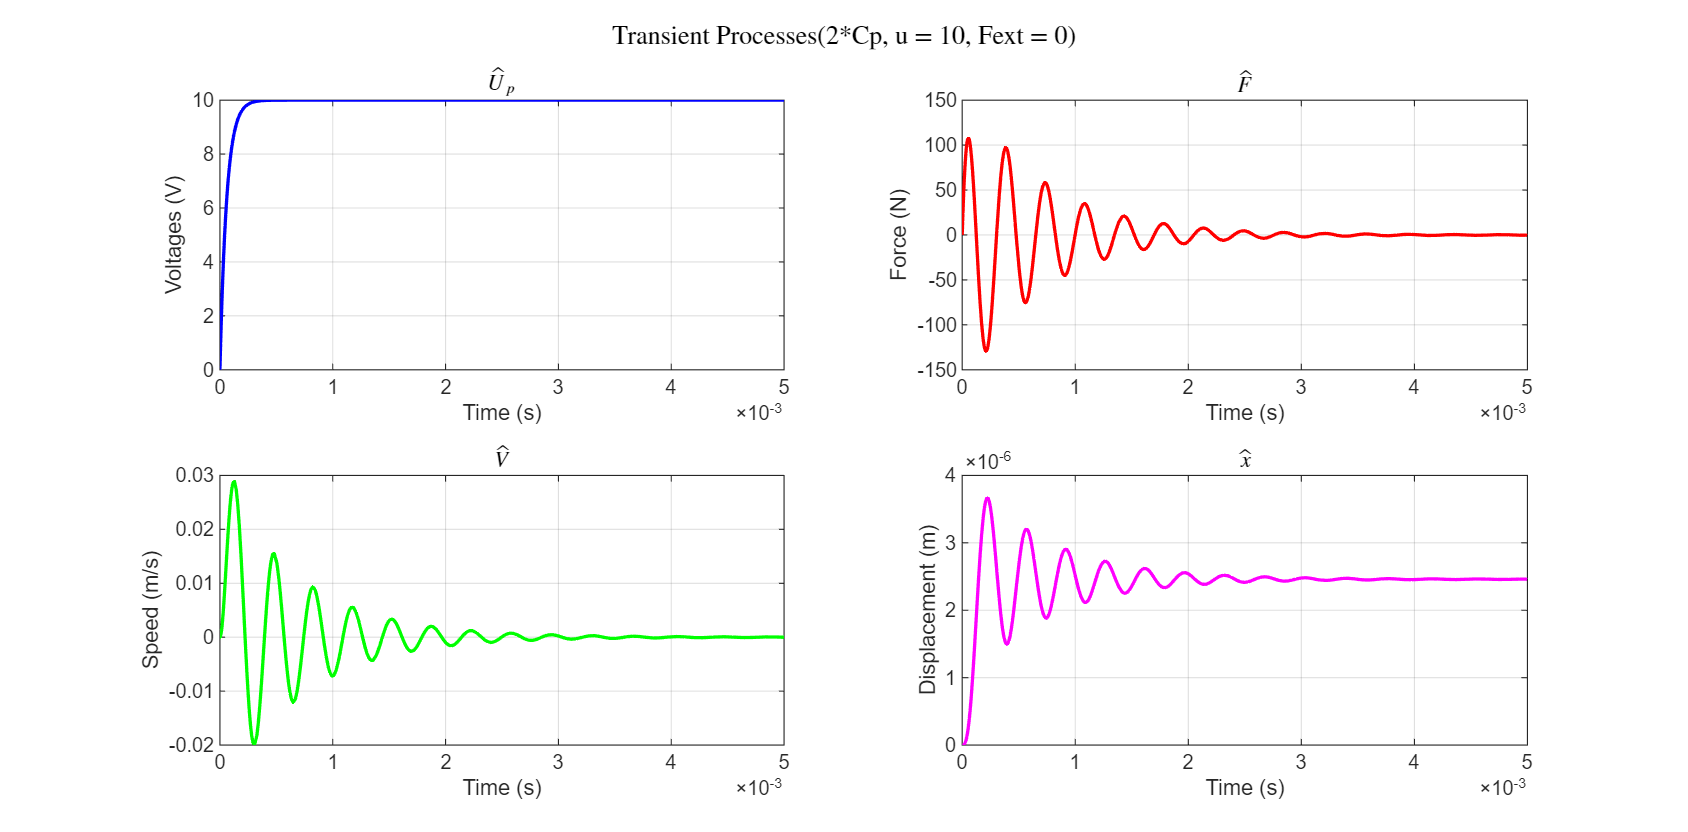

Cp = 2*variant.Cp;

## 6. Asymptotic logarithmic bode magnitude plot of piezoelectric actuator.

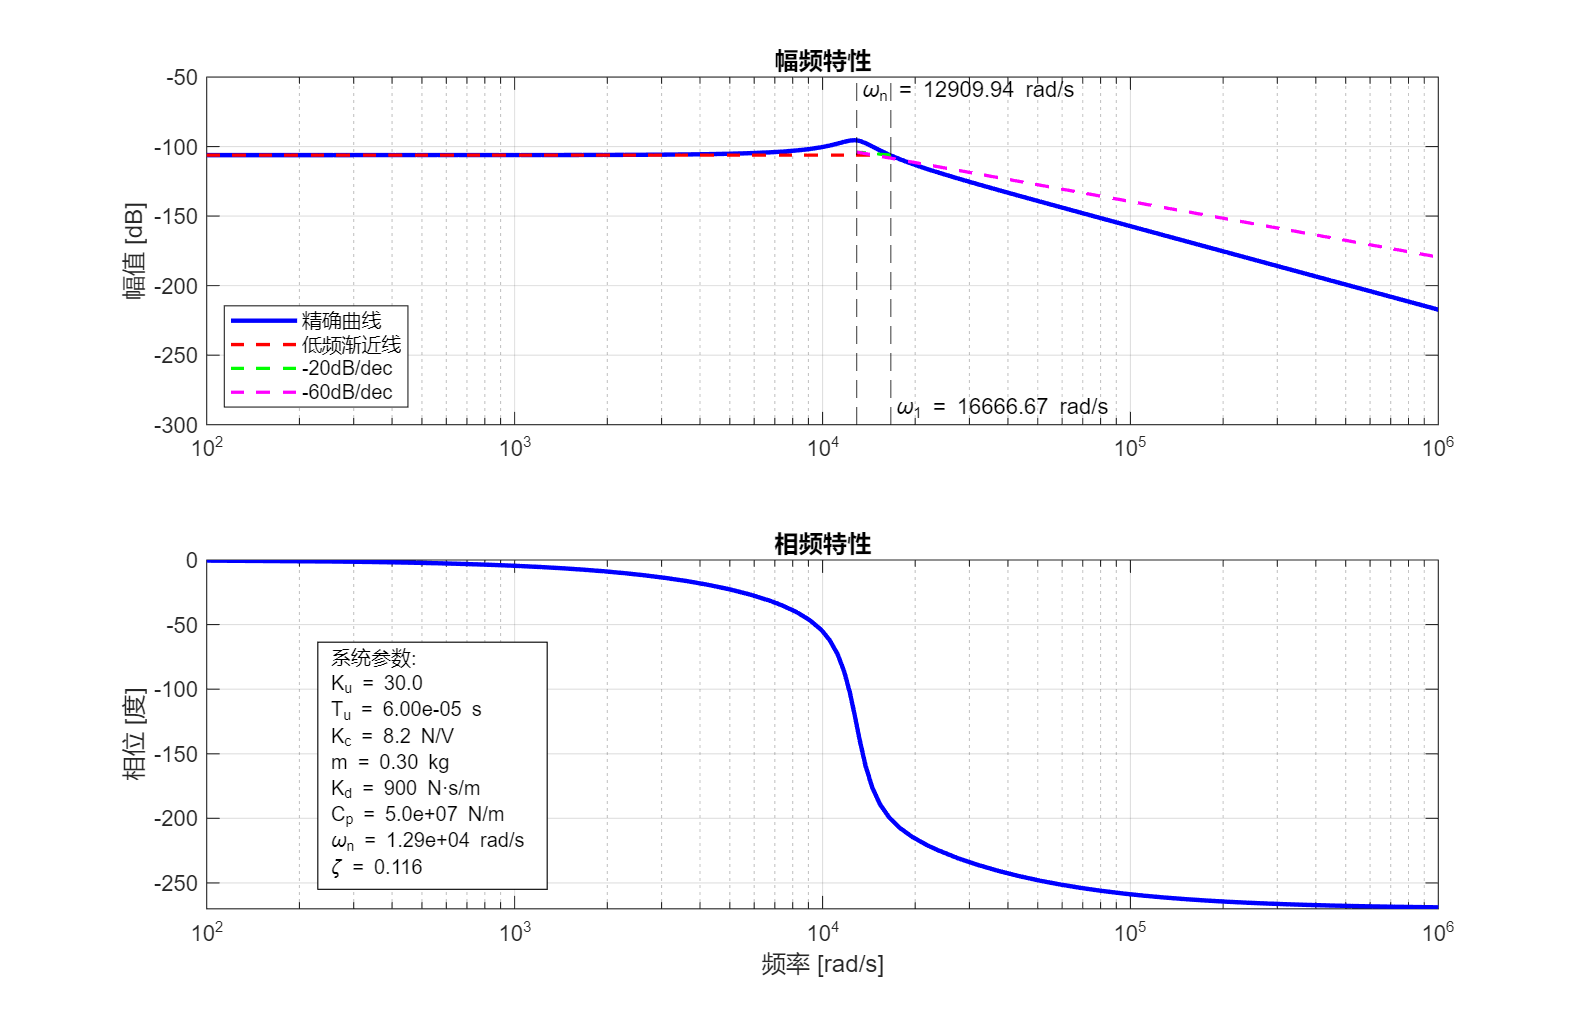

init_variant(variant);
Fext = 0;
Tmdl = 1;
plot_piezo_bode(Ku, Tu, Kc, m, Kd, Cp);

# Function

%% 初始化参数
function init_variant(variant)

    assignin('base', 'Cp', variant.Cp);
    assignin('base', 'm', variant.m);
    assignin('base', 'Kc', variant.Kc);
    assignin('base', 'Kd', variant.Kd);
    assignin('base', 'Tu', variant.Tu);
    assignin('base', 'Fext', variant.Fext);

    
end

function variant = get_pm_variant(k)
    % 定义全局表格（或通过 persistent 变量避免重复创建）
    persistent pm_table;
    if isempty(pm_table)
        pm_table = table();
        pm_table.Cp = [1.2e8; 0.5e8; 0.8e8; 1.5e8; 0.6e8; 3.2e6; 2.5e6; 1.8e6; 4.2e6; 2e6];
        pm_table.m = [0.8; 0.3; 0.5; 1.0; 0.5; 0.025; 0.01; 0.01; 0.25; 0.125];
        pm_table.Kc = [9.5; 8.2; 9.3; 12; 8.2; 6.5; 7.1; 5.2; 10; 7.5];
        pm_table.Kd = [1e3; 0.9e3; 0.8e3; 1.5e3; 0.9e3; 0.8e2; 0.7e2; 0.7e2; 0.75e2; 0.9e2];
        pm_table.Tu = [0.05e-3; 0.06e-3; 0.08e-3; 0.1e-3; 0.05e-3; 0.05e-3; 0.2e-3; 0.2e-3; 0.15e-3; 0.15e-3];
        pm_table.Fext = [100; 80; 75; 120; 50; 2; 1.2; 0.9; 3; 4];
        pm_table.Properties.RowNames = {'1', '2', '3', '4', '5', '6', '7', '8', '9', '0'};
    end
    
    % 检查 k 值并返回对应行
    k_str = num2str(k);
    if ismember(k_str, pm_table.Properties.RowNames)
        variant = pm_table(k_str, :);
    else
        error('Invalid k value. k must be between 0 and 9.');
    end
end


%% BODE
function plot_piezo_bode(Ku, Tu, Kc, m, Kd, Cp)
    
    % 创建传递函数
    num_amp = Ku;
    den_amp = [Tu 1];
    sys_amp = tf(num_amp, den_amp);
    
    num_pm = Kc;
    den_pm = [m Kd Cp];
    sys_pm = tf(num_pm, den_pm);
    sys_open = series(sys_amp, sys_pm);
    
    % 计算自然频率和阻尼比
    omega_n = sqrt(Cp/m);
    zeta = Kd/(2*sqrt(m*Cp));
    
    % 创建上下结构的图形窗口
    figure('Name', '压电执行器伯德图(上下结构)', 'Units', 'normalized', ...
           'Position', [0.1 0.1 0.7 0.8]);
    
    % 上子图：幅频特性
    subplot(2, 1, 1);
    [mag, ~, w] = bode(sys_open);
    mag_db = 20*log10(squeeze(mag));
    semilogx(w, mag_db, 'b', 'LineWidth', 2);
    hold on;
    
    % 绘制渐近线
    w_low = logspace(log10(min(w)), log10(1/Tu));
    mag_low = 20*log10(Ku*Kc/Cp)*ones(size(w_low));
    semilogx(w_low, mag_low, 'r--', 'LineWidth', 1.5);
    
    w_mid = logspace(log10(1/Tu), log10(omega_n));
    mag_mid = 20*log10(Ku*Kc/Cp) - 20*log10(w_mid*Tu);
    semilogx(w_mid, mag_mid, 'g--', 'LineWidth', 1.5);
    
    w_high = logspace(log10(omega_n), log10(max(w)));
    mag_high = 20*log10(Ku*Kc/Cp) - 20*log10(omega_n*Tu) - 40*log10(w_high/omega_n);
    semilogx(w_high, mag_high, 'm--', 'LineWidth', 1.5);
    
    % 标记转折频率
    xline(1/Tu, 'k--', sprintf('\\omega_1 = %.2f rad/s', 1/Tu), ...
          'LabelOrientation', 'horizontal', ...
          'LabelVerticalAlignment', 'bottom');
    xline(omega_n, 'k--', sprintf('\\omega_n = %.2f rad/s', omega_n), ...
          'LabelOrientation', 'horizontal', ...
          'LabelVerticalAlignment', 'top');
    
    title('幅频特性', 'FontWeight', 'bold');
    ylabel('幅值 [dB]');
    grid on;
    ylim([-300 -50]);
    legend('精确曲线', '低频渐近线', '-20dB/dec', '-60dB/dec', 'Location', 'southwest');
    
    % 下子图：相频特性
    subplot(2, 1, 2);
    [~, phase, w] = bode(sys_open);
    semilogx(w, squeeze(phase), 'b', 'LineWidth', 2);
    title('相频特性', 'FontWeight', 'bold');
    xlabel('频率 [rad/s]');
    ylabel('相位 [度]');
    grid on;
    ylim([-270 0]);
    
    % 系统参数文本框 - 调整到右侧
    param_str = sprintf([...
        '系统参数:\n' ...
        'K_u = %.1f\n' ...
        'T_u = %.2e s\n' ...
        'K_c = %.1f N/V\n' ...
        'm = %.2f kg\n' ...
        'K_d = %.0f N·s/m\n' ...
        'C_p = %.1e N/m\n' ...
        '\\omega_n = %.2e rad/s\n' ...
        '\\zeta = %.3f'], ...
        Ku, Tu, Kc, m, Kd, Cp, omega_n, zeta);
    
    annotation('textbox', [0.2 0.2 0.1 0.1], 'String', param_str, ...
               'FitBoxToText', 'on', 'BackgroundColor', 'w', ...
               'EdgeColor', 'k', 'FontSize', 9, ...
               'VerticalAlignment', 'middle', 'Interpreter', 'tex');
end
